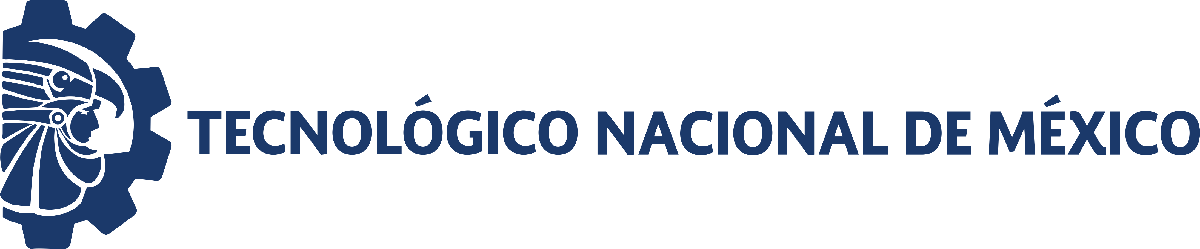                                    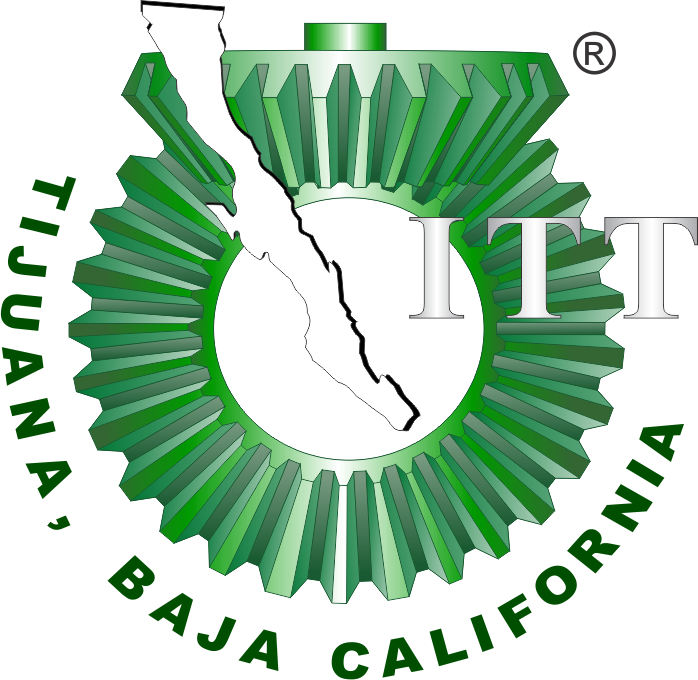

# **Understanding COVID-19 dynamics in Mexico through mathematical modelling, biostatistics and *****in silico *****experimentation**

Paul A. Valle, Yolocuauhtli Salazar, Luis N. Coria, Corina Plata, Alonso R. Diaz

Posgrado en Ciencias de la Ingeniería, Grupo de Investigación BioMath, Tecnológico Nacional de México / IT Tijuana, Blvd. Alberto Limón Padilla s/n, Tijuana 22454, México; paul.valle@tectijuana.edu.mx, luis.coria@tectijuana.edu.mx, alonso.diaz193@tectijuana.edu.mx

Departamento de Ciencias Básicas, Tecnológico Nacional de México / IT Tijuana, Calzada del Tecnológico 12950, Tijuana 22414, México; corina.plata@tectijuana.edu.mx

Posgrado en Ingeniería, Tecnológico Nacional de México / IT Durango, Blvd. Felipe Pescador 1830 ote., Durango 34080, México; ysalazar@itdurango.edu.mx

## Evolution of COVID-19 in Mexico 

The Government of Mexico provides, through the General Directorate of Epidemiology and CONAHCyT, an open data dashboard with national information regarding the number of confirmed cases, deaths and recoveries, among others, on the evolution of the COVID-19 pandemic in Mexico from February 26, 2020 to June 24, 2023. 

**Reference: **Gobierno de México (25/Junio/2023).  Datos abiertos COVID-19 México [On line]. [https://datos.covid-19.conacyt.mx/](https://datos.covid-19.conacyt.mx/)

## Data

### Confirmed infections and deaths nationwide [Recorded data]

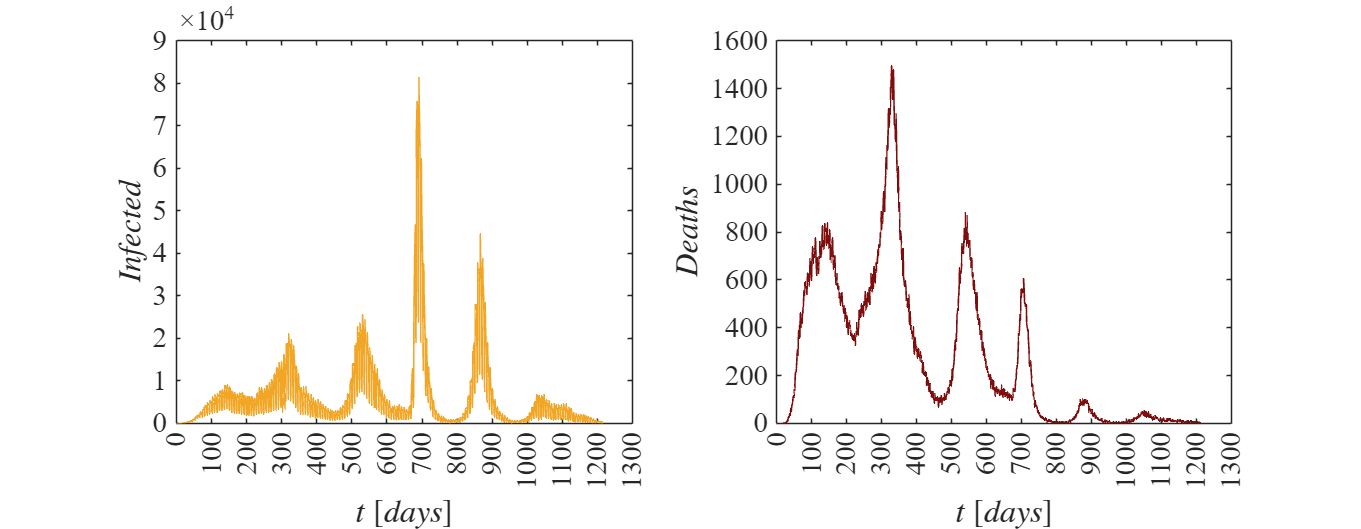

clc; clear;
data = readmatrix("data.xlsx");
to = data(:,2);     % Time [days]
So = data(:,3);     % Susceptible population [individuals]
Io = data(:,4);     % Cumulative infected [individuals]
Ro = data(:,5);     % Cumulative recovered [individuals]
Do = data(:,6);     % Cumulative deaths [individuals]
Ido = data(:,7);    % Infected per day [individuals]
Ddo = data(:,8);    % Deaths per day [individuals]
plotraw(to,Ido,Ddo,0)

### Confirmed infections and deaths nationwide [Normalized data]

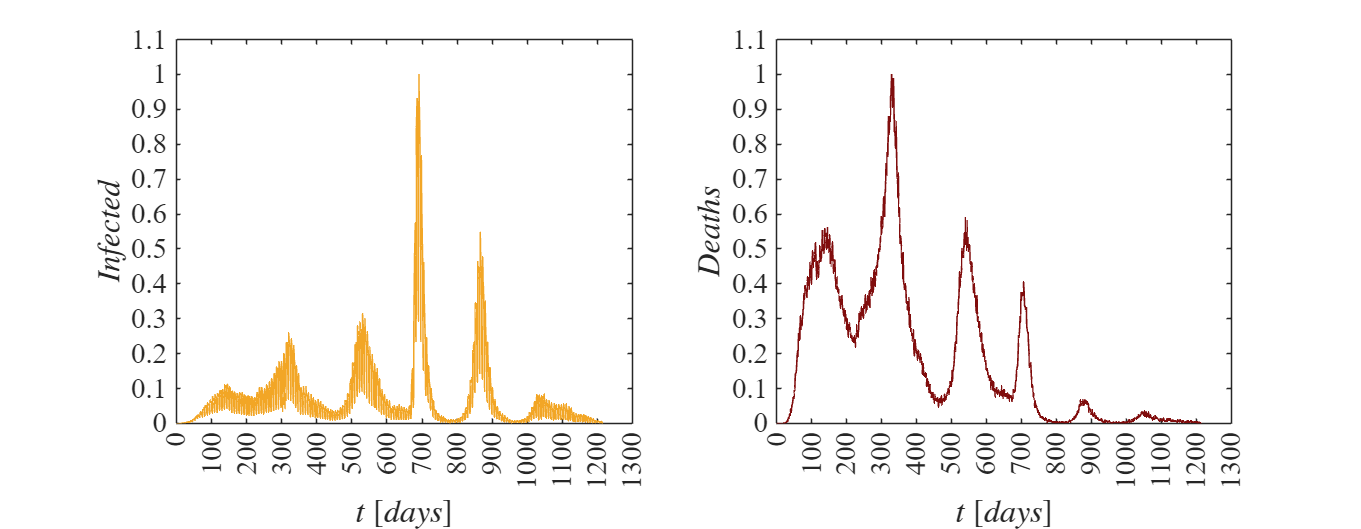

plotraw(to,Ido/max(Ido),Ddo/max(Ddo),1)

### Susceptible, Infected, Recovered and Deaths [Cumulative data]

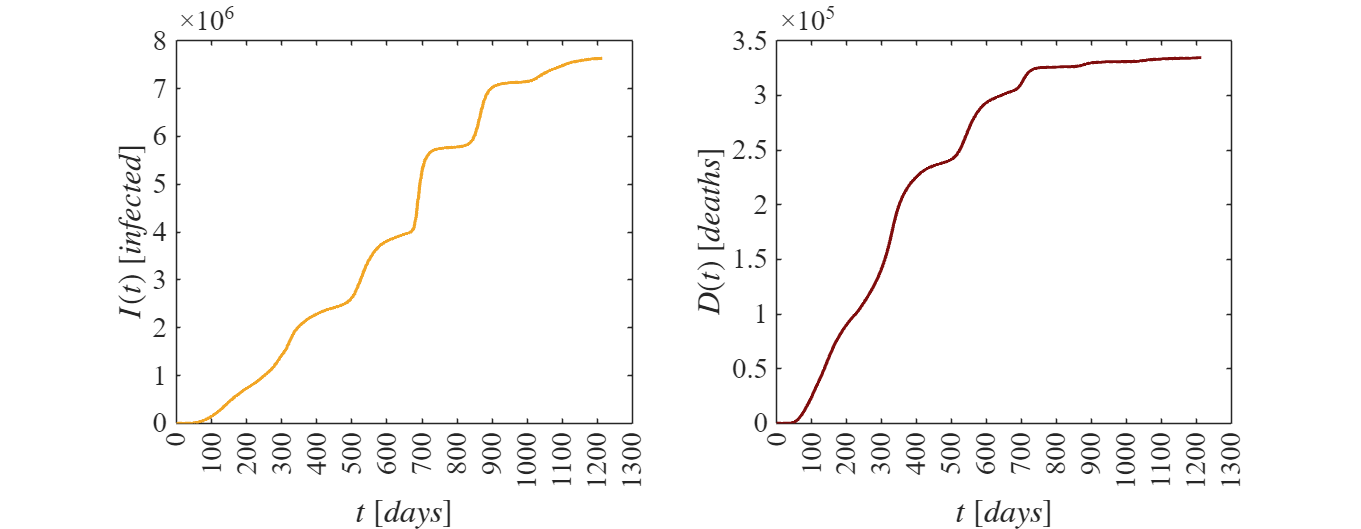

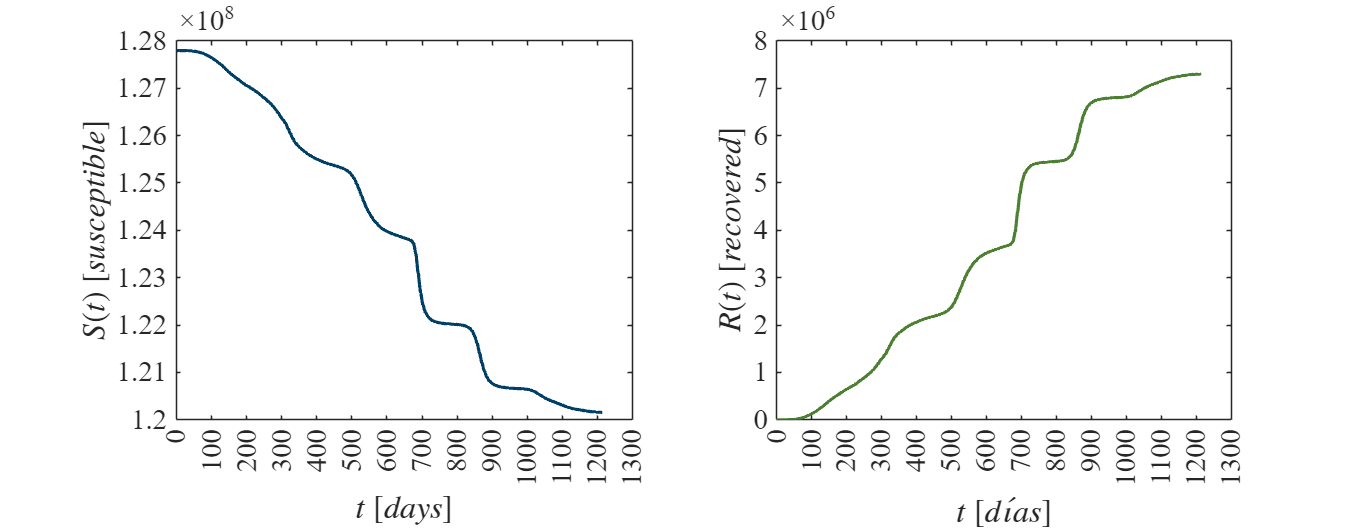

nn = 0; % [nn = 0: original; nn = 1: normalized]
plotdata(to,So,Io,Ro,Do,nn)

### Susceptible, Infected, Recovered and Deaths [Cumulative normalized data]

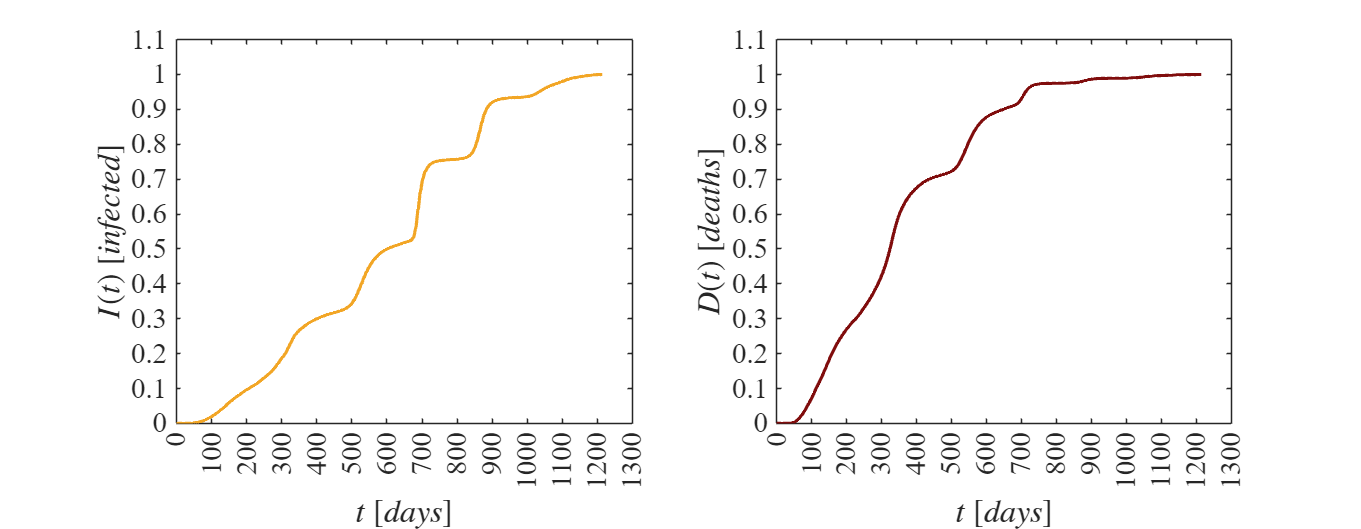

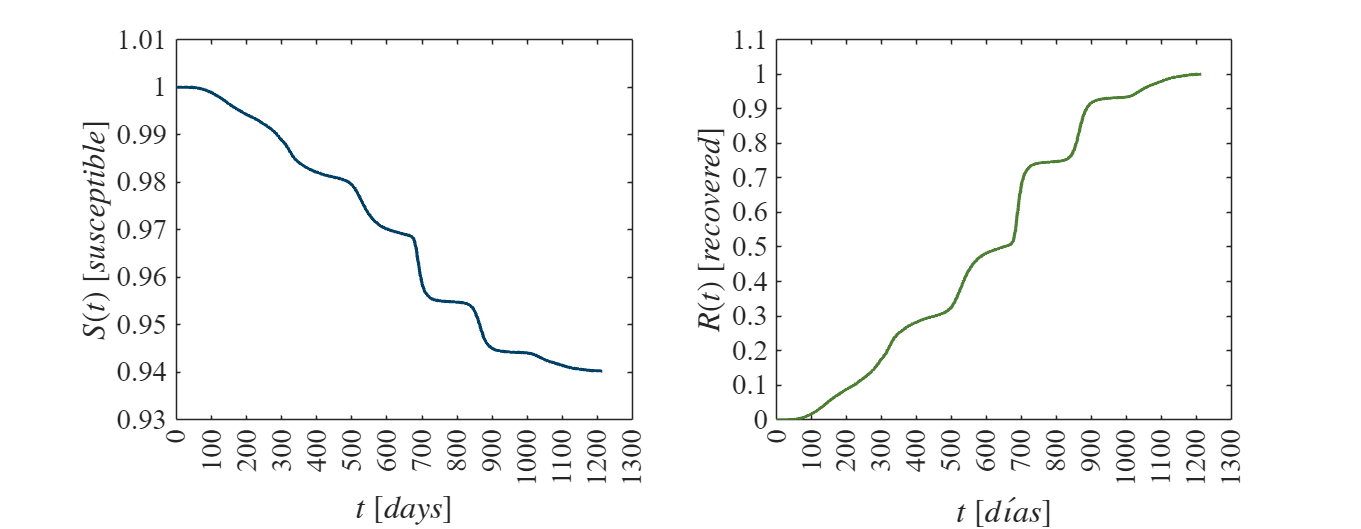

Sn = So/max(So);    % Susceptible population [individuals]
In = Io/max(Io);    % Cumulative recoveries [individuals]
Rn = Ro/max(Ro);    % Recupertados acumulados [individuos]
Dn = Do/max(Do);    % Cumulative deaths [individuals]
nn = 1; % [nn = 0: original; nn = 1: normalized]
fn = [Sn;In;Rn;Dn];
plotdata(to,Sn,In,Rn,Dn,nn)

## Nonlinear regression algorithm and goodness of fit

### Mathematical model

The model formulated to approximate the dynamics of COVID-19 in Mexico is given by the following four first-order ODEs:


$$$\dot{S} =-\rho _{1}S-I\left( \rho _{2}S-\rho _{3}t\right) $

$\dot{I} =\rho _{4}S+I\left( \rho _{5}S-\rho _{6}t\right) $

$\dot{R} =\rho _{7}I\left( R-\rho _{8}\right) ^{2}$

$\dot{D} =\rho _{9}I\left( D-\rho _{10}\right) ^{2}$$$


where, $$S(t)$$ is the population susceptible to contagion, $$I(t)$$ the people infected by the virus, $$R(t)$$ the recovered patients, and $$D(t)$$ the deceased individuals in Mexico.

### Nonlinear regression

rho0 = [1E-5;1E-4;1E-7;5E-4;5E-3;5E-6;5E-3;1;1E-2;1];
mdl = fitting_model(to,Sn,In,Rn,Dn,rho0);

Number of observed data: 4860
Number of parameters: 10
Degrees of freedom: 4850
t-Student value: 1.9605
 
    Parameters     Estimate         SE           MoE                  CI95                Pvalue  
    __________    __________    __________    __________    ________________________    __________

      rho1        2.6673e-05    7.0655e-06    1.3852e-05    1.2821e-05    4.0524e-05    0.00016186
      rho2        0.00017338    5.3523e-05    0.00010493    6.8449e-05    0.00027831     0.0012062
      rho3        1.3532e-07     5.009e-08    9.8199e-08    3.7119e-08    2.3352e-07     0.0069266
      rho4        0.00033095    4.2283e-06    8.2893e-06    0.00032266    0.00033924             0
      rho5         0.0042611    4.9331e-05    9.6712e-05     0.0041644     0.0043578           

**Estimate: **Value estimated by the nonlinear regression algorithm fitnlm.

**SE: **Standard error of the estimated value.

**MoE: **Margin of error of the estimated value.

**CI95: **95% confidence intervals for the estimated value.

**Pvalue: **P-value of the estimated value.

**Reference:** H. Motulsky, *Intuitive biostatistics: a nonmathematical guide to statistical thinking*. 4th ed. Oxford, New York, USA: Oxford University Press, 2014.

### *In silico experimentation*

**Desktop computer: **Desktop computer with a Ryzen 9 7950X processor with 192 GB of DDR5 CL40 RAM, a 12 GB NVIDIA GeForce RTX 4070 Ti graphics card and a 1 TB Samsung 990 Pro Gen 4 NVMe M.2 solid-state hard drive.

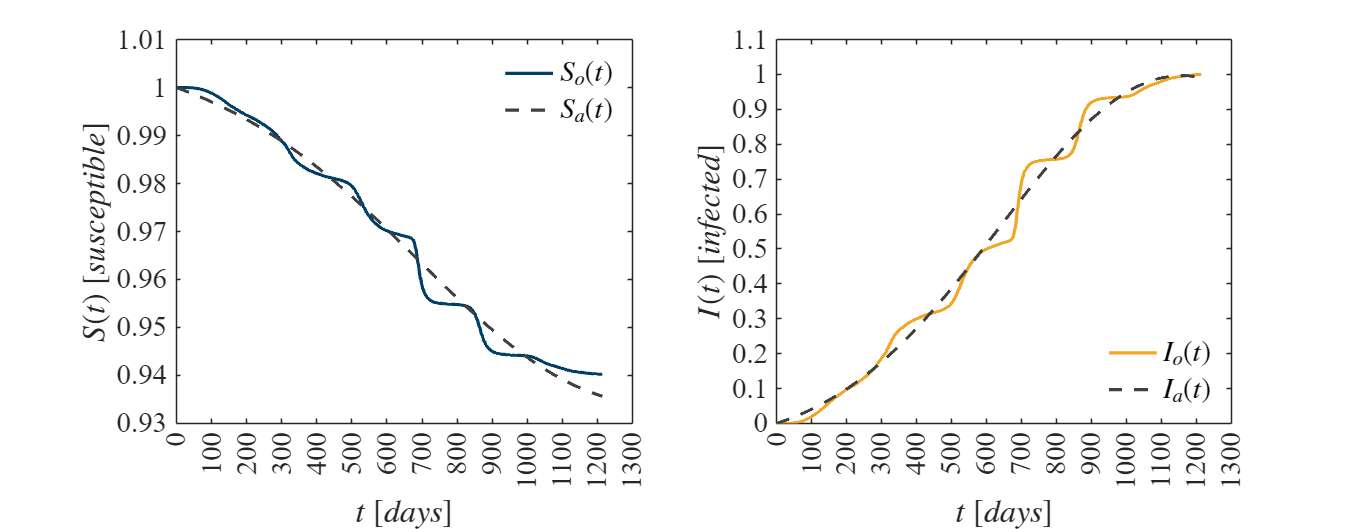

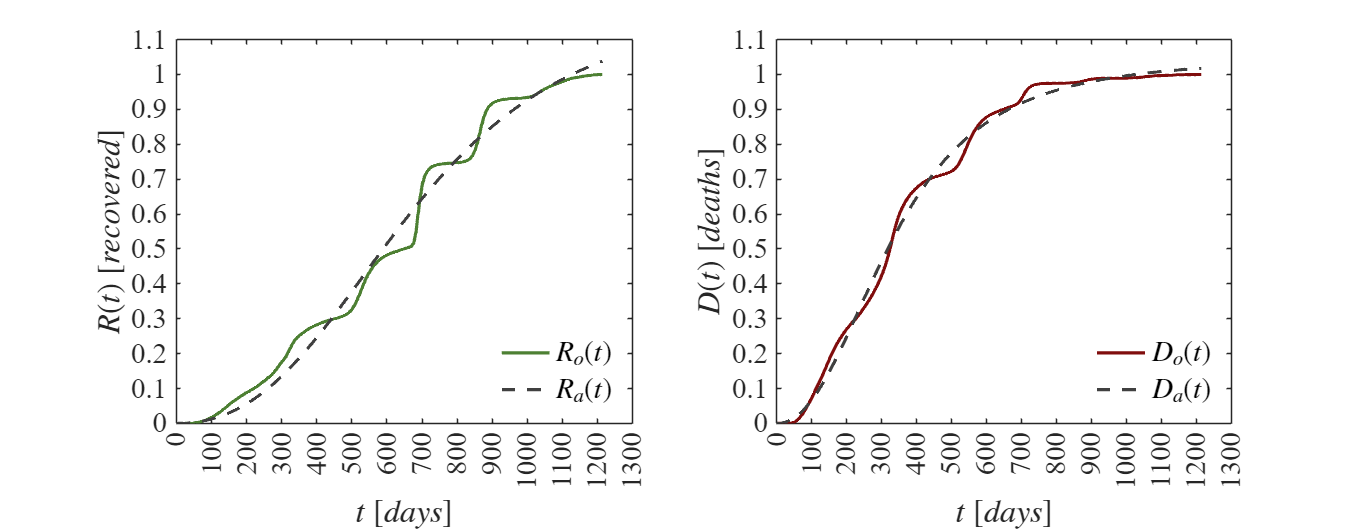

fa = reshape(mdl.Fitted,[],4); % Data approximated by the non-linear regression algorithm with the formulated model
Sa = fa(:,1); % Approximate susceptible population (normalized values)
Ia = fa(:,2); % Approximate accumulated infected (normalized values)
Ra = fa(:,3); % Approximate accumulated recovered (normalized values)
Da = fa(:,4); % Approximate accumulated deaths (normalized values)
plotresults(to,[Sn,Sa],[In,Ia],[Rn,Ra],[Dn,Da])

### Goodness of fit

K = numel(rho0); % Number of parameters
[R2S,~] = GOF(Sn,Sa,K); % R-squared for susceptible population
[R2I,~] = GOF(In,Ia,K); % R-squared for susceptible population
[R2R,~] = GOF(Rn,Ra,K); % R-squared for susceptible population
[R2D,~] = GOF(Dn,Da,K); % R-squared for susceptible population
AIC = mdl.ModelCriterion.AIC; % Akaike information criterion (AIC)
R2 = [R2S;R2I;R2R;R2D];
X_t = ['S(t)';'I(t)';'R(t)';'D(t)'];
R_squared = table(X_t,R2);
disp(R_squared); disp(['AIC = ',num2str(AIC)])

    X_t       R2   
    ____    _______

    S(t)    0.98835
    I(t)    0.99372
    R(t)    0.98936
    D(t)    0.99548

AIC = -21773.6469


## Functions

### Confirmed cases and deaths

function plotraw(t,Id,Dd,nn)
    set(figure(),'color','w'); 
    set(gcf,'units','centimeters','position',[1,1,36,14])
    FS = 18;
    
    subplot(1,2,1)
    hold on; grid off; box on
    plot(t,Id,'-','LineWidth',1,'Color',[0.95,0.65,0.15]);
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',FS)
    ylabel('$Infected$','Interpreter','latex','FontSize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    if nn == 0
        ylim([0 9E4]); yticks(0:1E4:9E4)
    elseif nn == 1
        ylim([0 1.1]); yticks(0:0.1:1.1)
    end
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on; grid off; box on
    plot(t,Dd,'-','LineWidth',1,'Color',[0.5,0.05,0.05]);
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',FS)
    ylabel('$Deaths$','Interpreter','latex','FontSize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    set(gca,'FontName','Times New Roman','FontSize',FS)
    if nn == 0
        ylim([0 1600]); yticks(0:200:1600)
        exportgraphics(gcf,'rawdata.pdf','ContentType','vector')
        print('rawdata','-dsvg')
    elseif nn == 1
        ylim([0 1.1]); yticks(0:0.1:1.1)
        exportgraphics(gcf,'rawdatanormalized.pdf','ContentType','vector')
        print('rawdatanormalized','-dsvg')
    end
    
end

### Susceptible, Infected, Recovered and Deaths

function plotdata(t,S,I,R,D,nn)
    set(figure(),'color','w');
    set(gcf,'units','centimeters','position',[1,1,36,14])
    FS = 18;
    
    subplot(1,2,1)
    hold on; grid off; box on
    plot(t,I,'-','LineWidth',2,'Color',[0.95,0.65,0.15]);
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',FS)
    ylabel('$I(t)$ $[infected]$','Interpreter','latex','FontSize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    if nn == 0
        ylim([0 8E6]); yticks(0:1E6:8E6)
    elseif nn == 1
        ylim([0 1.1]); yticks(0:0.1:1.1)
    end
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on; grid off; box on
    plot(t,D,'-','LineWidth',2,'Color',[0.5,0.05,0.05]);
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',FS)
    ylabel('$D(t)$ $[deaths]$','Interpreter','latex','FontSize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    if nn == 0
        ylim([0 3.5E5]); yticks(0:0.5E5:3.5E5)
    elseif nn == 1
        ylim([0 1.1]); yticks(0:0.1:1.1)
    end
    set(gca,'FontName','Times New Roman','FontSize',FS)

    if nn == 0
        exportgraphics(gcf,'dataID.pdf','ContentType','vector')
        print('data','-dsvg')
    elseif nn == 1
        exportgraphics(gcf,'normalized.pdf','ContentType','vector')
        print('normalizedID','-dsvg')
    end
    
    
    set(figure(),'color','w');
    set(gcf,'units','centimeters','position',[1,1,36,14])
    subplot(1,2,1)
    hold on; grid off; box on
    plot(t,S,'-','LineWidth',2,'Color',[0,0.25,0.4]);
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',FS)
    ylabel('$S(t)$ $[susceptible]$','Interpreter','latex','FontSize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    if nn == 0
        ylim([1.2E8 1.28E8]); yticks(1.2E8:0.01E8:1.28E8)
    elseif nn == 1
        ylim([0.93 1.01]); yticks(0.93:0.01:1.01)
    end
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on; grid off; box on
    plot(t,R,'-','LineWidth',2,'Color',[0.3,0.5,0.2]);
    xlabel('$t$ $[d\acute{\imath}as]$','Interpreter','latex','FontSize',FS)
    ylabel('$R(t)$ $[recovered]$','Interpreter','latex','FontSize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    if nn == 0
        ylim([0 8E6]); yticks(0:1E6:8E6)
    elseif nn == 1
        ylim([0 1.1]); yticks(0:0.1:1.1)
    end
    set(gca,'FontName','Times New Roman','FontSize',FS)

    if nn == 0
        exportgraphics(gcf,'data.pdf','ContentType','vector')
        print('dataSR','-dsvg')
    elseif nn == 1
        exportgraphics(gcf,'normalized.pdf','ContentType','vector')
        print('normalizedSR','-dsvg')
    end
end

### Nonlinear regression algorithm

function mdl = fitting_model(to,So,Io,Ro,Do,rho0)
    fo = [So;Io;Ro;Do];
    to = [to;to;to;to];

    function fa = model(rho,to)
        rho1 = rho(1); rho2 = rho(2); rho3 = rho(3); rho4 = rho(4); rho5 = rho(5);
        rho6 = rho(6); rho7 = rho(7); rho8 = rho(8); rho9 = rho(9); rho10 = rho(10);
        to = reshape(to,[],4); to = to(:,1);
        dt = 1E-2;
        t = (0:dt:max(to))';
        n = round(max(to)/dt);
        S = zeros(n+1,1); S(1) = So(1);
        I = zeros(n+1,1); I(1) = Io(1);
        R = zeros(n+1,1); R(1) = Ro(1);
        D = zeros(n+1,1); D(1) = Do(1);

        for i = 1:n
            [fS,fI,fR,fD] = f(S(i),I(i),R(i),D(i),t(i));
            Sn = S(i) + fS*dt;
            In = I(i) + fI*dt;
            Rn = R(i) + fR*dt;
            Dn = D(i) + fD*dt;
            
            [fSn,fIn,fRn,fDn] = f(Sn,In,Rn,Dn,t(i));         
            S(i+1) = S(i) + (fS + fSn)*dt/2;
            I(i+1) = I(i) + (fI + fIn)*dt/2;
            R(i+1) = R(i) + (fR + fRn)*dt/2;
            D(i+1) = D(i) + (fD + fDn)*dt/2;
        end
        
        function [dS,dI,dR,dD] = f(S,I,R,D,t)
            dS = - rho1*S - (rho2*S - rho3*t)*I;
            dI = + rho4*S + (rho5*S - rho6*t)*I;
            dR = + rho7*I*(R - rho8)^2;
            dD = + rho9*I*(D - rho10)^2;
        end
   
        Si = zeros(length(to),1);
        Ii = zeros(length(to),1);
        Ri = zeros(length(to),1);
        Di = zeros(length(to),1);

        for i = 1:length(to)
            k = abs(t-to(i)) < 1E-9;
            Si(i) = S(k);
            Ii(i) = I(k);
            Ri(i) = R(k);
            Di(i) = D(k);
        end

        fa = [Si;Ii;Ri;Di];
    end

    mdl = fitnlm(to,fo,@model,rho0);
    
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['rho1 ';'rho2 ';'rho3 ';'rho4 ';'rho5 ';...
                  'rho6 ';'rho7 ';'rho8 ';'rho9 ';'rho10';];
    Results = table(Parameters,Estimate,SE,MoE,CI95,Pvalue);
    disp(['Number of observed data: ',num2str(numel(fo))])
    disp(['Number of parameters: ',num2str(numel(rho0))])
    disp(['Degrees of freedom: ',num2str(dof)])
    disp(['t-Student value: ',num2str(tval)])
    disp(' ')
    disp(Results)
end

### Bondad de ajuste

function [R2,AIC] = GOF(xo,xa,K)
% xo: Observed data
% xa: Approximate data
%  K: Number of parameters

    n = length(xo);
    RSS = 0; TSS = 0;
    
    for i = 1:n
        RSS = RSS + (xo(i) - xa(i))^2;
        TSS = TSS + (xo(i) - mean(xo))^2;
    end
    
    R2 = 1 - RSS/TSS;
    RMSE =  sqrt(RSS/n);
    Sigma2 = TSS/n;
    Sigma = sqrt(Sigma2);
    AIC = n*log(RSS/n) + 2*K +(2*K*(K+1))/(n-K-1);
end

### Model fitting results by nonlinear regression

function plotresults(t,S,I,R,D)
    set(figure(),'color','w');
    set(gcf,'units','centimeters','position',[1,1,36,14])
    FS = 18;
    
    subplot(1,2,1)
    hold on; grid off; box on
    plot(t,S(:,1),'-','LineWidth',2,'Color',[0,0.25,0.4]);
    plot(t,S(:,2),'--','LineWidth',2,'Color',[0.25,0.25,0.25]);
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$S(t)$ $[susceptible]$','interpreter','latex','fontsize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    ylim([0.93 1.01]); yticks(0.93:0.01:1.01)
    L = legend('$S_o(t)$','$S_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','NorthEast','box','off')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on; grid off; box on
    plot(t,I(:,1),'-','LineWidth',2,'Color',[0.95,0.65,0.15]);
    plot(t,I(:,2),'--','LineWidth',2,'Color',[0.25,0.25,0.25]);
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$I(t)$ $[infected]$','interpreter','latex','fontsize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    ylim([0 1.1]); yticks(0:0.1:1.1)
    L = legend('$I_o(t)$','$I_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','SouthEast','box','off')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'resultsSI.pdf','ContentType','vector')
    print('resultsSI','-dsvg')

    
    set(figure(),'color','w');
    set(gcf,'units','centimeters','position',[1,1,36,14])
    subplot(1,2,1)
    hold on; grid off; box on
    plot(t,R(:,1),'-','LineWidth',2,'Color',[0.3,0.5,0.2]);
    plot(t,R(:,2),'--','LineWidth',2,'Color',[0.25,0.25,0.25]);
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$R(t)$ $[recovered]$','interpreter','latex','fontsize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    ylim([0 1.1]); yticks(0:0.1:1.1)
    L = legend('$R_o(t)$','$R_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','SouthEast','box','off')
    set(gca,'FontName','Times New Roman','FontSize',FS)
    
    subplot(1,2,2)
    hold on; grid off; box on
    plot(t,D(:,1),'-','LineWidth',2,'Color',[0.5,0.05,0.05]);
    plot(t,D(:,2),'--','LineWidth',2,'Color',[0.25,0.25,0.25]);
    xlabel('$t$ $[days]$','interpreter','latex','fontsize',FS)
    ylabel('$D(t)$ $[deaths]$','interpreter','latex','fontsize',FS)
    xlim([0 1300]); xticks(0:100:1300)
    ylim([0 1.1]); yticks(0:0.1:1.1)
    L = legend('$D_o(t)$','$D_a(t)$');
    set(L,'Interpreter','Latex','FontSize',FS,'Location','SouthEast','box','off')
    set(gca,'FontName','Times New Roman','FontSize',FS)

    exportgraphics(gcf,'resultsRD.pdf','ContentType','vector')
    print('resultsRD','-dsvg')
end